theta=1

theta = 1

V35=1

V35 = 1

V30=1

V30 = 1

V25=1

V25 = 1

V20=1

V20 = 1

V15=1

V15 = 1

V10=V35;

V08=1;
V06=1;
V04=1;

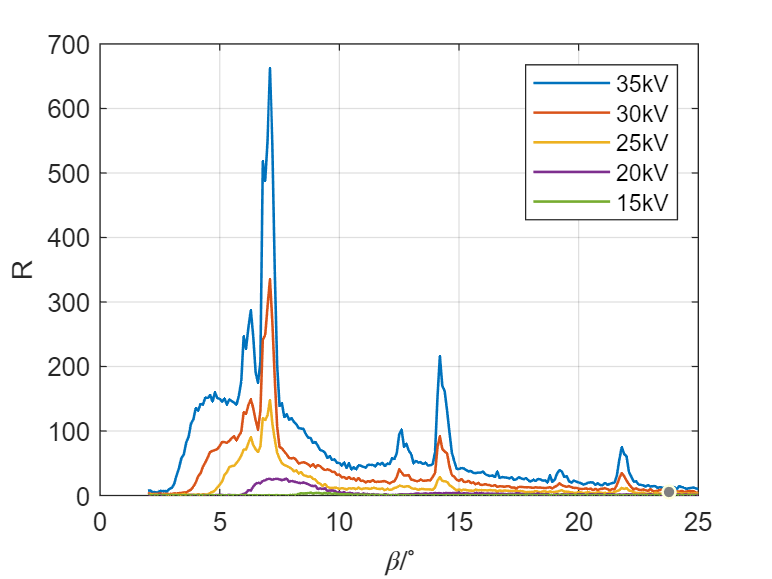

figure
plot(theta,V35,'linewidth',1)
hold on
plot(theta,V30,'linewidth',1)
plot(theta,V25,'linewidth',1)
plot(theta,V20,'linewidth',1)
plot(theta,V15,'linewidth',1)
legend('35kV','30kV','25kV','20kV','15kV')
xlabel('$\beta/^{\circ}$','Interpreter','latex')
ylabel('R')
grid on

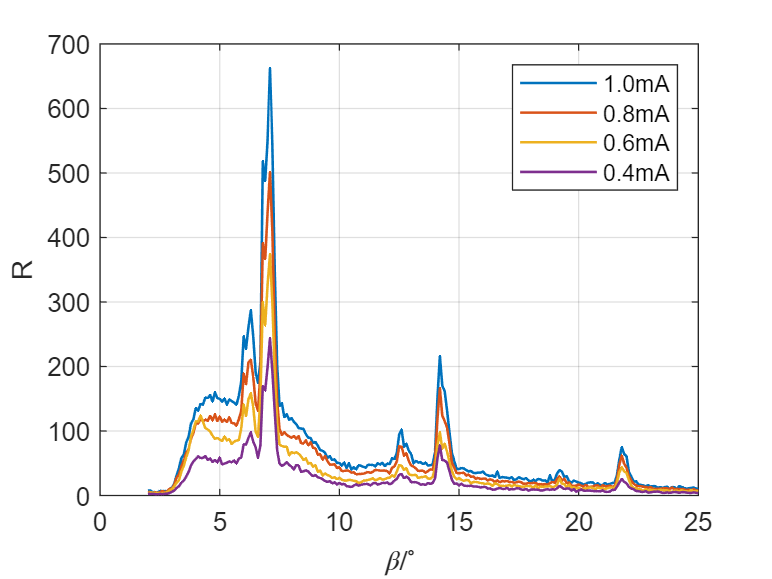

figure
plot(theta,V10,'linewidth',1)
hold on
plot(theta,V08,'linewidth',1)
plot(theta,V06,'linewidth',1)
plot(theta,V04,'linewidth',1)
legend('1.0mA','0.8mA','0.6mA','0.4mA')
xlabel('$\beta/^{\circ}$','Interpreter','latex')
ylabel('R')
grid on

lamdh=[0.0285 	0.0364 	0.0472 	0.0599 	0.0814];
lambrg=[0.0354 	0.0413 	0.0496 	0.0620 	0.0827];
U=[35,30,25,20,15];

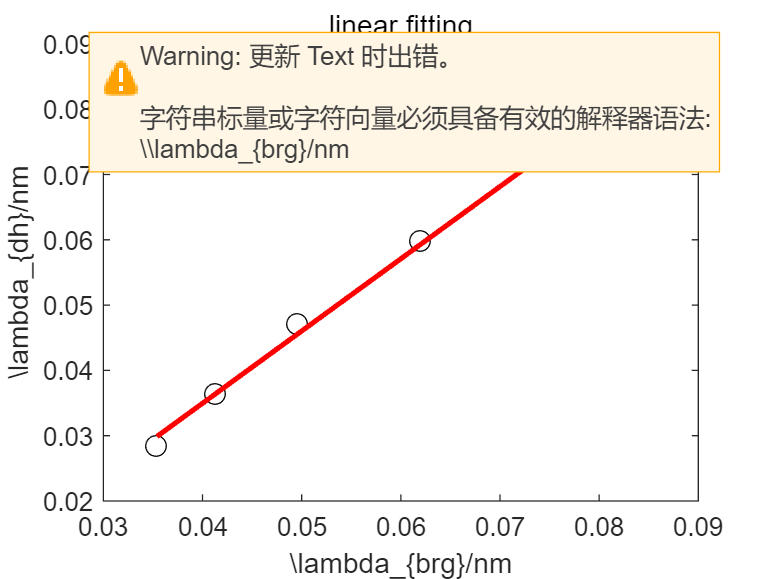

% 假设您的两组数据分别为 x 和 y
x = lambrg;  % 替换为您的实际 x 数据
y = lamdh;  % 替换为您的实际 y 数据

% 进行线性拟合
p = polyfit(x, y, 1);

% 获取拟合参数
slope = p(1);      % 斜率
intercept = p(2);  % 截距

% 计算 R-squared 值
yfit = polyval(p, x);
yresid = y - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(y)-1) * var(y);
Rsq = 1 - SSresid/SStotal;

% 创建拟合线的点
x_fit = linspace(min(x), max(x), 100);
y_fit = polyval(p, x_fit);

% 绘制散点图和拟合线
figure;
plot(x, y, 'ko', 'MarkerSize', 8);
hold on;
plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
xlabel('\lambda_{brg}/nm','Interpreter','latex');
ylabel('\lambda_{dh}/nm','Interpreter','latex');
title('linear fitting');
legend('data', 'fitting line');

% 在图上显示拟合方程和R^2值
equation = sprintf('y = %.4fx + %.4f', slope, intercept);
Rsq_text = sprintf('R^2 = %.4f', Rsq);
text(min(x), max(y), {equation, Rsq_text}, 'VerticalAlignment', 'top');


% 输出拟合结果
fprintf('拟合方程: y = %.4fx + %.4f\n', slope, intercept);

拟合方程: y = 1.1065x + -0.0093


fprintf('R-squared: %.4f\n', Rsq);

R-squared: 0.9968


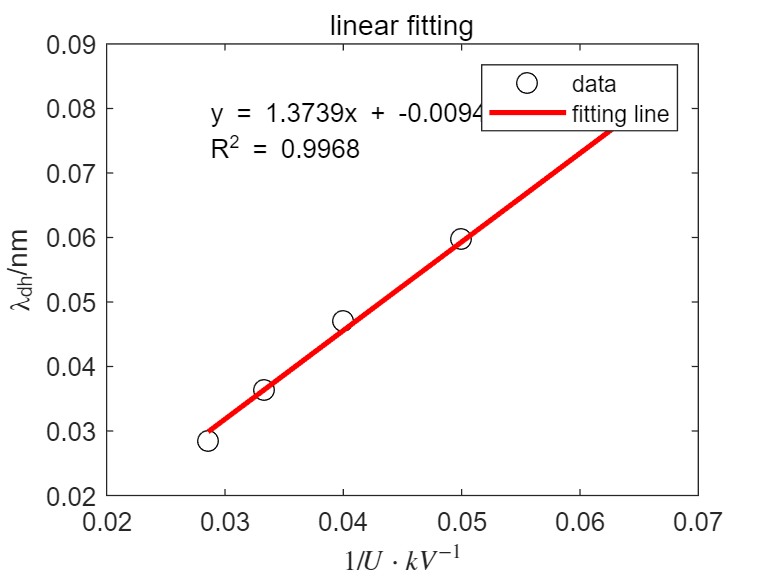

figure
% 假设您的两组数据分别为 x 和 y
x =1./U;  % 替换为您的实际 x 数据
y = lamdh;  % 替换为您的实际 y 数据

% 进行线性拟合
p = polyfit(x, y, 1);

% 获取拟合参数
slope = p(1);      % 斜率
intercept = p(2);  % 截距

% 计算 R-squared 值
yfit = polyval(p, x);
yresid = y - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(y)-1) * var(y);
Rsq = 1 - SSresid/SStotal;

% 创建拟合线的点
x_fit = linspace(min(x), max(x), 100);
y_fit = polyval(p, x_fit);

% 绘制散点图和拟合线
figure;
plot(x, y, 'ko', 'MarkerSize', 8);
hold on;
plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
xlabel('$1/U \cdot kV^{-1}$','Interpreter','latex');
ylabel('\lambda_{dh}/nm','Interpreter','tex');
title('linear fitting');
legend('data', 'fitting line');

% 在图上显示拟合方程和R^2值
equation = sprintf('y = %.4fx + %.4f', slope, intercept);
Rsq_text = sprintf('R^2 = %.4f', Rsq);
text(min(x), max(y), {equation, Rsq_text}, 'VerticalAlignment', 'top');


% 输出拟合结果
fprintf('拟合方程: y = %.4fx + %.4f\n', slope, intercept);

拟合方程: y = 1.3739x + -0.0094


fprintf('R-squared: %.4f\n', Rsq);

R-squared: 0.9968
